# [Solutions] Controlled bond expansion (CBE) DMRG for ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for CBE-DMRG

The complete version is uploaded as `DMRG/DMRG_GS_CBE.m`. Compare with your implementation!

## Solution to Exercise (b): Error analysis

We repeat the CBE-DMRG calculations for the free spinful fermions on a tight-binding chain, for different values of `Nkeep`. We use the same initial MPS obtained from the iterative diagonalization, with the lowest value of `Nkeep`.

clear

% system parameters
t = 1; % hopping amplitude
L = 30; % number of sites in a chain

% CBE-DMRG parameters
Nkeep = (50:50:300);
Nsweep = 8;
delta = 0.1;

E0_exact = nonIntTB(ones(L-1,1)*t)*2; % *2 due to two spins

% Local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(6,6);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = Z*F(:,:,1);
Hloc{3,1} = Z*F(:,:,2);
Hloc{4,1} = Hloc{2,1}';
Hloc{5,1} = Hloc{3,1}';
Hloc{6,2} = -t*F(:,:,1)';
Hloc{6,3} = -t*F(:,:,2)';
Hloc{6,4} = -t*F(:,:,1);
Hloc{6,5} = -t*F(:,:,2);
Hloc{6,6} = I;

Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

% initial MPS
Minit = cell(1,L);

Hprev = 1; % initialize Hamiltonian with 1, as we will use MPO
Aprev = 1; % identity tensor for the dummy leg

for itN = (1:L)
    % add new site
    Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
    Hnow = updateLeft(Hprev,3,Anow,Hs{itN},4,Anow);

    Hmat = Hnow(:,:,1);
    [V,D] = eig((Hmat+Hmat')/2);
    [D,ids] = sort(diag(D),'ascend');
    if itN < L
        Ntr = min([numel(D);Nkeep(1)]);
    else
        Ntr = 1;
    end
    V = V(:,ids(1:Ntr));
    
    Anow = contract(Anow,3,2,V,2,1,[1 3 2]);

    Minit{itN} = Anow;
    
    Hprev = contract(Hnow,3,2,V,2,1);
    Hprev = contract(V',2,2,Hprev,3,1,[1 3 2]);
    Aprev = Anow;
end

Run calculations.

% result arrays
E0s = zeros(1,numel(Nkeep));
Eiters = cell(1,numel(Nkeep));
dws = zeros(1,numel(Nkeep));
varEs = zeros(1,numel(Nkeep));

for itk = (1:numel(Nkeep))
    [M,E0s(itk),Eiters{itk},~,dw] = DMRG_GS_CBE (Minit,Hs,Nkeep(itk),Nsweep,delta);
    dws(itk) = sum(dw(:,end));
    varEs(itk) = varE_2site(M,Hs);
end

22-11-08 15:57:12 | CBE-DMRG: ground state search
22-11-08 15:57:12 | # of sites = 30, Nkeep = 50, # of sweeps = 8 x 2
22-11-08 15:57:13 | Sweep #1/16 (right -> left) : Energy = -37.37494
22-11-08 15:57:14 | Sweep #2/16 (left -> right) : Energy = -37.45959
22-11-08 15:57:14 | Sweep #3/16 (right -> left) : Energy = -37.47658
22-11-08 15:57:15 | Sweep #4/16 (left -> right) : Energy = -37.47949
22-11-08 15:57:15 | Sweep #5/16 (right -> left) : Energy = -37.47987
22-11-08 15:57:16 | Sweep #6/16 (left -> right) : Energy = -37.47996
22-11-08 15:57:16 | Sweep #7/16 (right -> left) : Energy = -37.48
22-11-08 15:57:17 | Sweep #8/16 (left -> right) : Energy = -37.48004
22-11-08 15:57:17 | Sweep #9/16 (right -> left) : Energy = -37.48008
22-11-08 15:57:18 | Sweep #10/16 (left -> right) : Energy = -37.48011
22-11-08 15:57:19 | Sweep #11/16 (right -> left) : Energy = -37.48013
22-11-08 15:57:19 | Sweep #12/16 (left -> right) : Energy = -37.48015
22-11-08 15:57:20 | Sweep #13/16 (right -> left) : En

Elapsed time: 0.3137s, CPU time: 3.36s, Avg # of cores: 10.71
22-11-08 15:57:22 | Memory usage : 5.54GiB


22-11-08 15:57:22 | CBE-DMRG: ground state search
22-11-08 15:57:22 | # of sites = 30, Nkeep = 100, # of sweeps = 8 x 2
22-11-08 15:57:23 | Sweep #1/16 (right -> left) : Energy = -37.37789
22-11-08 15:57:23 | Sweep #2/16 (left -> right) : Energy = -37.46243
22-11-08 15:57:24 | Sweep #3/16 (right -> left) : Energy = -37.48357
22-11-08 15:57:26 | Sweep #4/16 (left -> right) : Energy = -37.48667
22-11-08 15:57:27 | Sweep #5/16 (right -> left) : Energy = -37.48689
22-11-08 15:57:29 | Sweep #6/16 (left -> right) : Energy = -37.4869
22-11-08 15:57:31 | Sweep #7/16 (right -> left) : Energy = -37.4869
22-11-08 15:57:32 | Sweep #8/16 (left -> right) : Energy = -37.4869
22-11-08 15:57:34 | Sweep #9/16 (right -> left) : Energy = -37.4869
22-11-08 15:57:36 | Sweep #10/16 (left -> right) : Energy = -37.4869
22-11-08 15:57:38 | Sweep #11/16 (right -> left) : Energy = -37.4869
22-11-08 15:57:40 | Sweep #12/16 (left -> right) : Energy = -37.4869
22-11-08 15:57:41 | Sweep #13/16 (right -> left) : Energ

Elapsed time: 0.8609s, CPU time: 7.02s, Avg # of cores: 8.154
22-11-08 15:57:48 | Memory usage : 5.54GiB


22-11-08 15:57:48 | CBE-DMRG: ground state search
22-11-08 15:57:48 | # of sites = 30, Nkeep = 150, # of sweeps = 8 x 2
22-11-08 15:57:49 | Sweep #1/16 (right -> left) : Energy = -37.38469
22-11-08 15:57:50 | Sweep #2/16 (left -> right) : Energy = -37.46679
22-11-08 15:57:51 | Sweep #3/16 (right -> left) : Energy = -37.48492
22-11-08 15:57:53 | Sweep #4/16 (left -> right) : Energy = -37.48691
22-11-08 15:57:56 | Sweep #5/16 (right -> left) : Energy = -37.48712
22-11-08 15:57:59 | Sweep #6/16 (left -> right) : Energy = -37.48724
22-11-08 15:58:03 | Sweep #7/16 (right -> left) : Energy = -37.48726
22-11-08 15:58:07 | Sweep #8/16 (left -> right) : Energy = -37.48726
22-11-08 15:58:11 | Sweep #9/16 (right -> left) : Energy = -37.48726
22-11-08 15:58:15 | Sweep #10/16 (left -> right) : Energy = -37.48726
22-11-08 15:58:20 | Sweep #11/16 (right -> left) : Energy = -37.48726
22-11-08 15:58:24 | Sweep #12/16 (left -> right) : Energy = -37.48726
22-11-08 15:58:28 | Sweep #13/16 (right -> left) 

Elapsed time: 1.774s, CPU time: 13.09s, Avg # of cores: 7.38
22-11-08 15:58:43 | Memory usage : 5.53GiB


22-11-08 15:58:43 | CBE-DMRG: ground state search
22-11-08 15:58:43 | # of sites = 30, Nkeep = 200, # of sweeps = 8 x 2
22-11-08 15:58:43 | Sweep #1/16 (right -> left) : Energy = -37.38685
22-11-08 15:58:45 | Sweep #2/16 (left -> right) : Energy = -37.46856
22-11-08 15:58:46 | Sweep #3/16 (right -> left) : Energy = -37.48553
22-11-08 15:58:49 | Sweep #4/16 (left -> right) : Energy = -37.4871
22-11-08 15:58:53 | Sweep #5/16 (right -> left) : Energy = -37.48725
22-11-08 15:58:57 | Sweep #6/16 (left -> right) : Energy = -37.48728
22-11-08 15:59:03 | Sweep #7/16 (right -> left) : Energy = -37.4873
22-11-08 15:59:09 | Sweep #8/16 (left -> right) : Energy = -37.4873
22-11-08 15:59:15 | Sweep #9/16 (right -> left) : Energy = -37.4873
22-11-08 15:59:22 | Sweep #10/16 (left -> right) : Energy = -37.4873
22-11-08 15:59:30 | Sweep #11/16 (right -> left) : Energy = -37.4873
22-11-08 15:59:37 | Sweep #12/16 (left -> right) : Energy = -37.4873
22-11-08 15:59:44 | Sweep #13/16 (right -> left) : Energ

Elapsed time: 3.358s, CPU time: 23.21s, Avg # of cores: 6.911
22-11-08 16:00:09 | Memory usage : 5.56GiB


22-11-08 16:00:09 | CBE-DMRG: ground state search
22-11-08 16:00:09 | # of sites = 30, Nkeep = 250, # of sweeps = 8 x 2
22-11-08 16:00:10 | Sweep #1/16 (right -> left) : Energy = -37.38586
22-11-08 16:00:11 | Sweep #2/16 (left -> right) : Energy = -37.46872
22-11-08 16:00:14 | Sweep #3/16 (right -> left) : Energy = -37.48576
22-11-08 16:00:17 | Sweep #4/16 (left -> right) : Energy = -37.48721
22-11-08 16:00:22 | Sweep #5/16 (right -> left) : Energy = -37.48728
22-11-08 16:00:28 | Sweep #6/16 (left -> right) : Energy = -37.4873
22-11-08 16:00:36 | Sweep #7/16 (right -> left) : Energy = -37.48731
22-11-08 16:00:45 | Sweep #8/16 (left -> right) : Energy = -37.48732
22-11-08 16:00:57 | Sweep #9/16 (right -> left) : Energy = -37.48732
22-11-08 16:01:09 | Sweep #10/16 (left -> right) : Energy = -37.48732
22-11-08 16:01:21 | Sweep #11/16 (right -> left) : Energy = -37.48732
22-11-08 16:01:33 | Sweep #12/16 (left -> right) : Energy = -37.48732
22-11-08 16:01:45 | Sweep #13/16 (right -> left) :

Elapsed time: 5.473s, CPU time: 37.41s, Avg # of cores: 6.836
22-11-08 16:02:27 | Memory usage : 5.56GiB


22-11-08 16:02:27 | CBE-DMRG: ground state search
22-11-08 16:02:27 | # of sites = 30, Nkeep = 300, # of sweeps = 8 x 2
22-11-08 16:02:28 | Sweep #1/16 (right -> left) : Energy = -37.38604
22-11-08 16:02:29 | Sweep #2/16 (left -> right) : Energy = -37.46779
22-11-08 16:02:32 | Sweep #3/16 (right -> left) : Energy = -37.48574
22-11-08 16:02:37 | Sweep #4/16 (left -> right) : Energy = -37.48723
22-11-08 16:02:43 | Sweep #5/16 (right -> left) : Energy = -37.4873
22-11-08 16:02:51 | Sweep #6/16 (left -> right) : Energy = -37.48731
22-11-08 16:03:01 | Sweep #7/16 (right -> left) : Energy = -37.48732
22-11-08 16:03:15 | Sweep #8/16 (left -> right) : Energy = -37.48732
22-11-08 16:03:33 | Sweep #9/16 (right -> left) : Energy = -37.48732
22-11-08 16:03:52 | Sweep #10/16 (left -> right) : Energy = -37.48732
22-11-08 16:04:09 | Sweep #11/16 (right -> left) : Energy = -37.48732
22-11-08 16:04:25 | Sweep #12/16 (left -> right) : Energy = -37.48732
22-11-08 16:04:42 | Sweep #13/16 (right -> left) :

Elapsed time: 8.255s, CPU time: 55.35s, Avg # of cores: 6.705
22-11-08 16:05:41 | Memory usage : 5.56GiB


Let's see how the variational energy decreases with iterations, for different values of `Nkeep`.

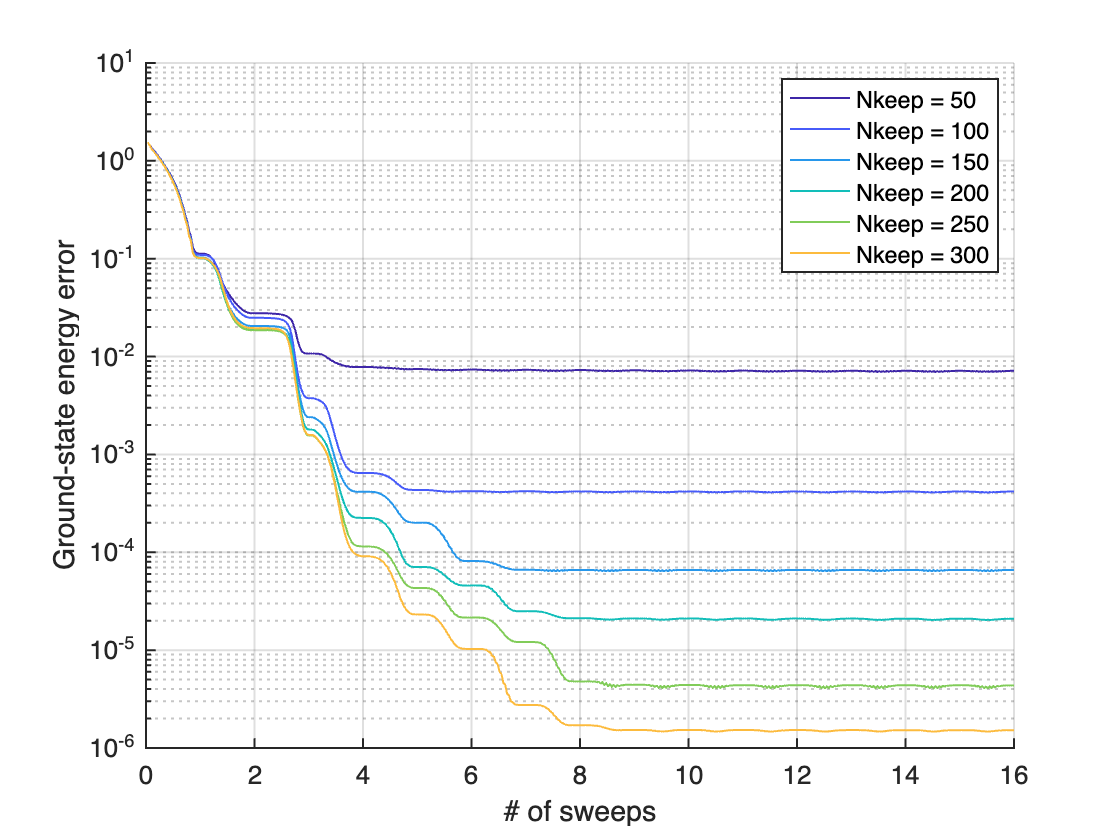

legs = cell(1,numel(Nkeep));
clrs = parula(round(numel(Nkeep)*1.2));

figure;
hold on;
for itk = (1:numel(Nkeep))
    plot((1:numel(Eiters{itk}))/(L-1),Eiters{itk}(:)-E0_exact, ...
        'Color',clrs(itk,:),'LineWidth',1);
    legs{itk} = sprintf('Nkeep = %i',Nkeep(itk));
end
hold off;
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');
legend(legs);

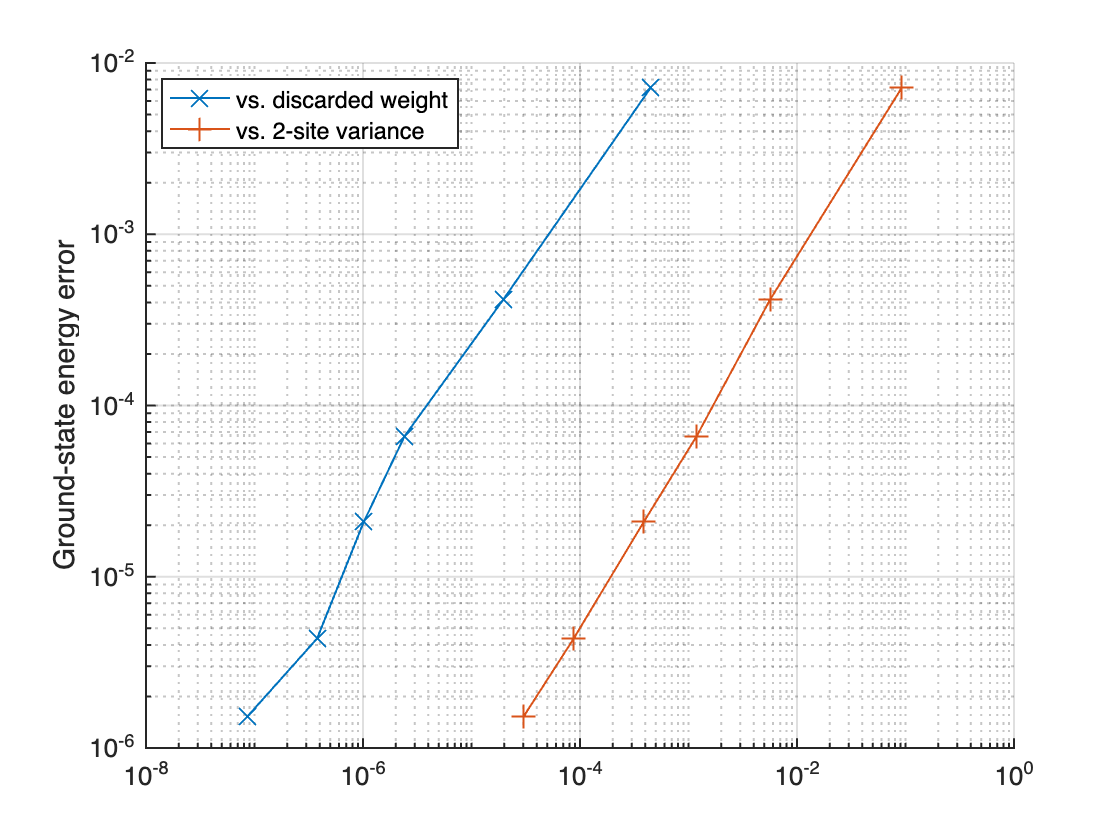

figure;
hold on;
plot(dws,E0s-E0_exact,'LineWidth',1,'Marker','x','MarkerSize',12);
plot(varEs,E0s-E0_exact,'LineWidth',1,'Marker','+','MarkerSize',12);
set(gca,'XScale','log','YScale','log','FontSize',13,'LineWidth',1);
grid on;
ylabel('Ground-state energy error');
legend({'vs. discarded weight','vs. 2-site variance'},'Location','northwest');

We find that the ground-state energy error scales linearly against both the discarded weight and the two-site variance.